# ***Chapter 2 - Risk and Modern Portfolio Theory***

## *Section A: Prerequisite Statistics*

- *A ****random variable**** x ~ f(x), where f(x) is a probability distribution function, usually f(x) is pdf (probability density function) for a continuous distribution, and pmf (prob. mass function) for a discrete distribution.*

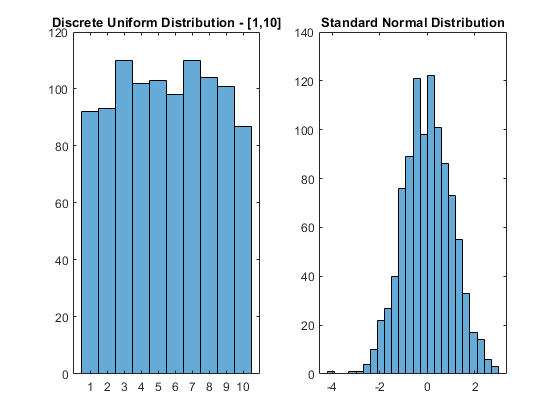

%   the number of simulated random variables
N=1000;
%   A Discrete Uniform Distribution [1,10]
X=randi(10,N,1);
subplot(1,2,1)
histogram(X)
title('Discrete Uniform Distribution - [1,10]')
xticks([1:10])
%   A Standard Normal Distribution N(0,1)
X=randn(N,1);
subplot(1,2,2)
histogram(X)
title('Standard Normal Distribution')

- ***Moments ****measure shapes of a distribution, and a finite number of moments may completely characterize a distribution's properties for most distributions of interest.  Given that a random variable X follows a distribution,then the distribution's *$K_{\mathrm{th}}$* moment is defined as *$E\left\lbrack X^K \right\rbrack$.

            Mean: $\mu=E[X]$.

            Variance: $\sigma^2=E[(X-\mu)^2]$. (the second central moment, and the volatility $\sigma$ is also called the **standard deviation**.)

            [Skewness](https://en.wikipedia.org/wiki/Skewness): $\gamma=\frac{E[(X-\mu)^3]}{\sigma^3}$. (the third standardized moment)

            [Kurtosis](https://en.wikipedia.org/wiki/Kurtosis): $\kappa=\frac{E[(X-\mu)^4]}{\sigma^4}$. (the fourth standardized moment)

close();
N=10000;
%   simulate X where X~N(0,1), i.e., X conforms to the standard normal distribution
X=randn(N,1);
%   sample mean. 
mean_est=mean(X);
%   sample standard deviation 
sigma_est=std(X);
%   sample skewness
skew_est=skewness(X);
%   sampel kurtosis
kurt_est=kurtosis(X);
fprintf('mean_est=%.2f.\nsigma_est=%.2f.\nskew_est=%.2f.\nkurt_est=%.2f.\n',mean_est,sigma_est,skew_est,kurt_est);

mean_est=-0.00.
sigma_est=0.98.
skew_est=0.02.
kurt_est=2.95.


- [***Normal Distribution***](https://en.wikipedia.org/wiki/Normal_distribution)***.**** Also called Gaussian Distribution. For a univariate normal distribution with mean *$\mu$* and variance *$\sigma^2
$*: *$f(x)=\frac{1}{2\pi\sigma^2}\cdot e^{\frac{-(x-\mu)^2}{2\sigma^2}}$*.  In quantitative financial analysis, most asset returns are assumed to be normally distributed in financial analysis. For example, stock prices in the Black-Scholes pricing framework are log-normally distribued, i.e., ****stock returns are assumed to be normally distributed****. However, it's important to test the validity of this normal distribution assuption.*

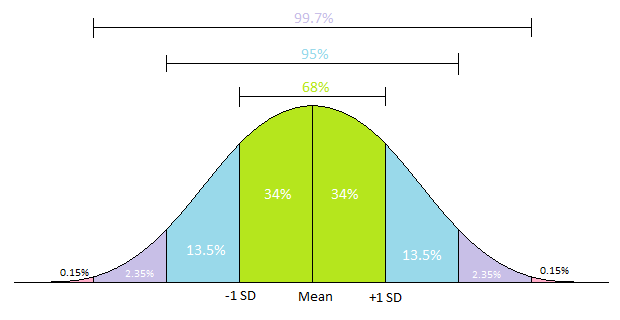

%   load monthly return information for asset classes in the CAPM model
[blah,blah,rawraw]=xlsread('CAPM_AssetClasses.xls');
ac_name=rawraw(1,2:end);
ac_mret=cell2mat(rawraw(3:242,2:end));

%   the asset classes loaded
ac_name'

ans = 12×1 cell array
    {'Fixed-Income: Treasury Inflation Protected Securities (TIPS)'     }
    {'Fixed-Income: U.S. Treasury Bonds and Investment Grade Corp Bonds'}
    {'Fixed-Income: U.S. High Yield Corp Bonds'                         }
    {'Fixed-Income: Non U.S. Sovereign Bonds'                           }
    {'Equities: U.S. Large Cap Growth'                                  }
    {'Equities: U.S. Large Cap Value'                                   }
    {'Equities: U.S. Small Cap Growth'                                  }
    {'Equities: U.S. Small Cap Value'                                   }
    {'Equities: Developed Countries Non-US '                            }
    {'Equities: Emerging Markets'                                       }
    {'Commodities'                                                      }
    {'Real Estate'                                                      }



%   Choose One Asset Class
cur_ac=input('Choose An Asset Class (1-12): ');

%   test of normality
if cur_ac>=1 & cur_ac<=12
    
    close();
    fprintf('------- %s -------\n',ac_name{cur_ac});
    
    %   monthly return vector
    mret_vec=ac_mret(:,cur_ac);
    subplot(1,2,1);
    histogram(mret_vec);
    title('Monthly Return Historgram');
    subplot(1,2,2);
    normplot(mret_vec);
    
    % Jarque-Bera Test
    % h=1 if reject normal distribution
    [h,p]=jbtest(mret_vec);
    fprintf('Jarque-Bera Test: h=%d, p-val=%.4f.\n',h,p);
    
    % One-sample Kolmogorov-Smirnov test
    % h=1 if reject normal distribution
    [h,p]=kstest((mret_vec-nanmean(mret_vec))/nanstd(mret_vec));
    fprintf('KS Test: h=%d, p-val=%.4f.\n',h,p);
end

Undefined variable "ac_name" or class "ac_name".

- ***Covariance and Correlation. ****Covariance and correlation both measure bivariate relationship of two random variables, while correlation doesn't account for variance levels of individual random variables. They have the same sign and are used to identify linear relationship between two variables. A positive (negative) covariance/correlation value indicates that when one variable moves in one direction, the other tends to move in the same (opposite) direction contemporarily.*

Given two random variables X and Y, 

**Covariance**: $Cov(X,Y)=E[(X-\mu_X)(Y-\mu_Y)]$,

**Correlation**: $Corr(X,Y)=\frac{Cov(X,Y)}{\sigma_X\sigma_Y}$.

% Equity Markets: Developed Countries Non-US vs. Emerging Countries
ac_name(9:10)

ans = 1×2 cell array
    {'Equities: Developed Countries Non-US '}    {'Equities: Emerging Markets'}


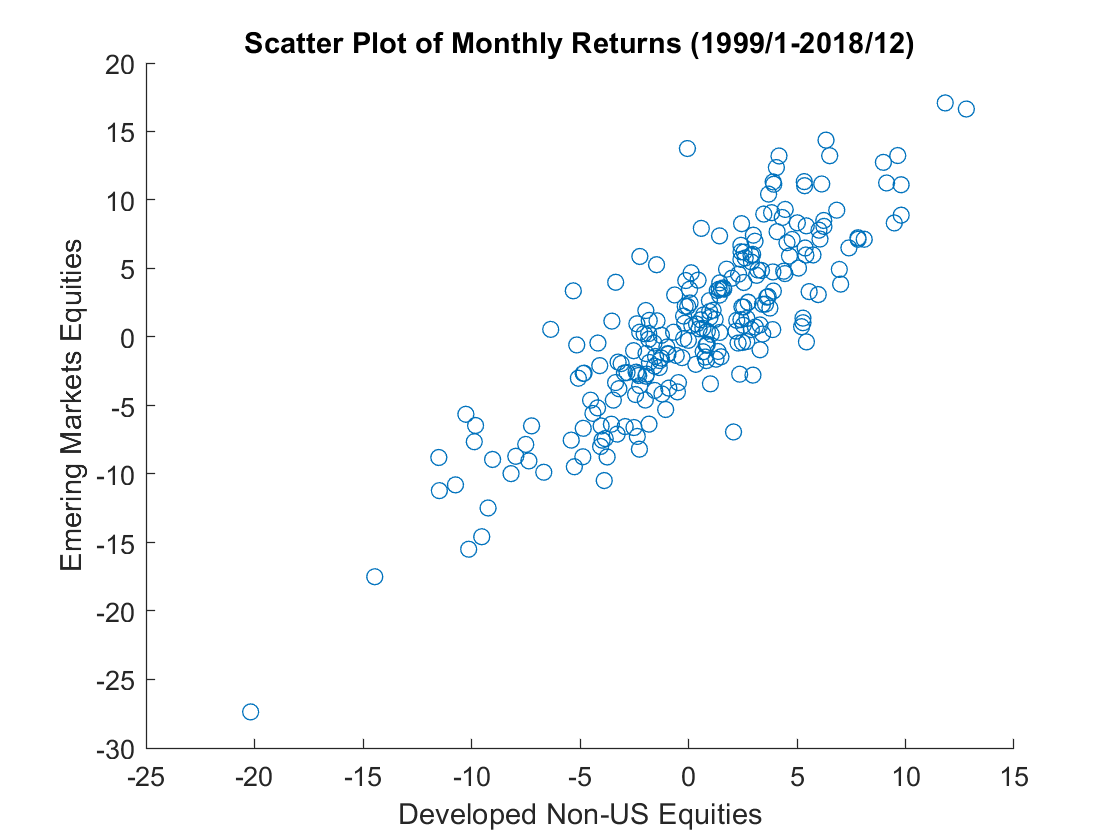

DM_mret=ac_mret(:,9);
EM_mret=ac_mret(:,10);

%   scatter plot
close();
scatter(DM_mret,EM_mret);
title('Scatter Plot of Monthly Returns (1999/1-2018/12)');
xlabel('Developed Non-US Equities');
ylabel('Emering Markets Equities');


%   calculate the covariance of the two variables
COV_mat=nancov(DM_mret,EM_mret)

COV_mat =    22.1948   25.2154
   25.2154   39.6454


covariance=COV_mat(1,2)

covariance = 25.2154


%   standard deviations of the two variables
sigma_vec=sqrt(diag(COV_mat))

sigma_vec =     4.7111
    6.2965



%   correlation of the two variables
correlation=covariance/(sigma_vec(1)*sigma_vec(2))

correlation = 0.8500


%   test the significance of correlation: http://janda.org/c10/Lectures/topic06/L24-significanceR.htm
%   can also use Matlab function corrcoef()
[R,P,RL,RU] = corrcoef([DM_mret,EM_mret],'Alpha',0.01)

R =     1.0000    0.8500
    0.8500    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.7965
    0.7965    1.0000


RU =     1.0000    0.8904
    0.8904    1.0000


More on Covariance: $Cov(X,Y)=E[(X-\mu_x)(Y-\mu_y)]=E[XY]-E[X]E[Y].$

- 
$$Cov(X,Y)=0 <=> Corr(X,Y)=0.$$


- If X and Y are independent, then $Cov(X,Y)=0.$

- If $Cov(X,Y)=0$, then X and Y are uncorrelated. (Note: uncorrelated is not necessarily independent. Counter example: X=Z~N(0,1), Y=Z^2.)

- If both X and Y are normally distributed (bivariate), then uncorrelation implies independence.

- Covariance/correlation between two random variables doesn't change for constant shifts on variable values, i.e., $Cov(X-const1,Y-const2)=Cov(X,Y).$

- Covariance summation rule: $Cov(\sum_iX_i,\sum_jY_j)=\sum_i\sum_jCov(X_i,Y_j).$

- Covariance measures are time-frequency dependent quantities.

        (Example)  Given security A and security B have daily return observation $\{X_t\}$ and $\{Y_t\}$ respectively, assuming daily returns are all i.i.d. for each of the two time series and no correlation exists for any non-contemparaneous obervation pair, then we have:


$$\sigma_{m,AB}=Cov(\sum_{t=1}^{21}X_t,\sum_{t=1}^{21}Y_t)=\sum_{t_1=1}^{21}\sum_{t_2=1}^{21}Cov(X_{t_1},Y_{t_2})=\sum_{t=1}^{21}Cov(X_t,Y_t)=21\cdot\sigma_{d,AB}.$$


## *Section B: Risk Metrics*

How to measure the risk of investing in an individual asset or a portfolio of assets? Here are some criteria a valid risk measure should satisfy:

- An objective measure but not a personal view

- Applicable both to individual assets and to portfolios

- Users are able to caculate realized risk in the past and to forecast future risk on certain accurate levels

**Standard Deviation** (i.e., **volatility** which measures the spread of the distribution about its mean) is the most-commonly-used risk measure in analyzing investment returns. The distribution of investments returns describes probabilities of all possible return incomes. Standard deviation, under the assumption that returns follow a normal distribution, fully determines return uncertainties. *Even though not all asset returns are normally distributed, people still use standard deviation as risk measure for most investments. (Why? 1) MPT assumption. 2) Apple-to-apple comparison of risk.)*

#### *Other Risk Metrics*

- *Semivariance, or downside risk*

         Crtics of the standardard deviation point out that standard deviation measures the possiblities of returns both above and below the mean. They argue that investors do not perceive dispersion of above-mean returns as risk. Semivariance is defined in analogy to variance, but using only returns below the mean. A variant of semivariance is target semivariance, which focuses on returns below a target (e.g., a common return target is zero).

          Problems with semivariance/downside risk: (*Note: those problems alsoMark apply to risk metriecs discussed below*)

- Its definition is not as unambiguous as that of variance (standard deviation) and statistical properties are not well known. 

- Aggregating semivariance from individual assets to portfolios is extremely difficult.

- Given most returns are reasonably symmetric, semivariance could simply be proportional to variance and contains no more inforamtion.

- Even if returns are not symmetric, those asymetries are not stable over time therefore using past obervations may not help future forecasts.

- Half observations are not used so that we may lose statistical accuracy.

%   monthly returns of emerging market equities
mret_vec=EM_mret;

%   sample mean of monthly returns
mean_monthly=nanmean(mret_vec)

mean_monthly = 0.8841


%   variance of monthly returns
variance_monthly=nanvar(mret_vec)

variance_monthly = 39.6454


%   annualized variance
variance_ann=variance_monthly*12

variance_ann = 475.7447


%   annuzlied volatility (standard deviation)
volatility_ann=sqrt(variance_ann)

volatility_ann = 21.8116


%   semivariance (for all returns below mean)
semi_variance=var(mret_vec(mret_vec<mean_monthly))

semi_variance = 19.6236


%   annualized semi-variance
semi_variance_ann=12*semi_variance

semi_variance_ann = 235.4832


%   annualized semi-volatility
semi_volatility_ann=sqrt(semi_variance_ann)

semi_volatility_ann = 15.3455

- *Shortfall Probability *

          Defined as the probability that the return will lie below some target ammount, the shortfall probability is one risk metric perhaps closely related to an intuitive conception of what risk is. 

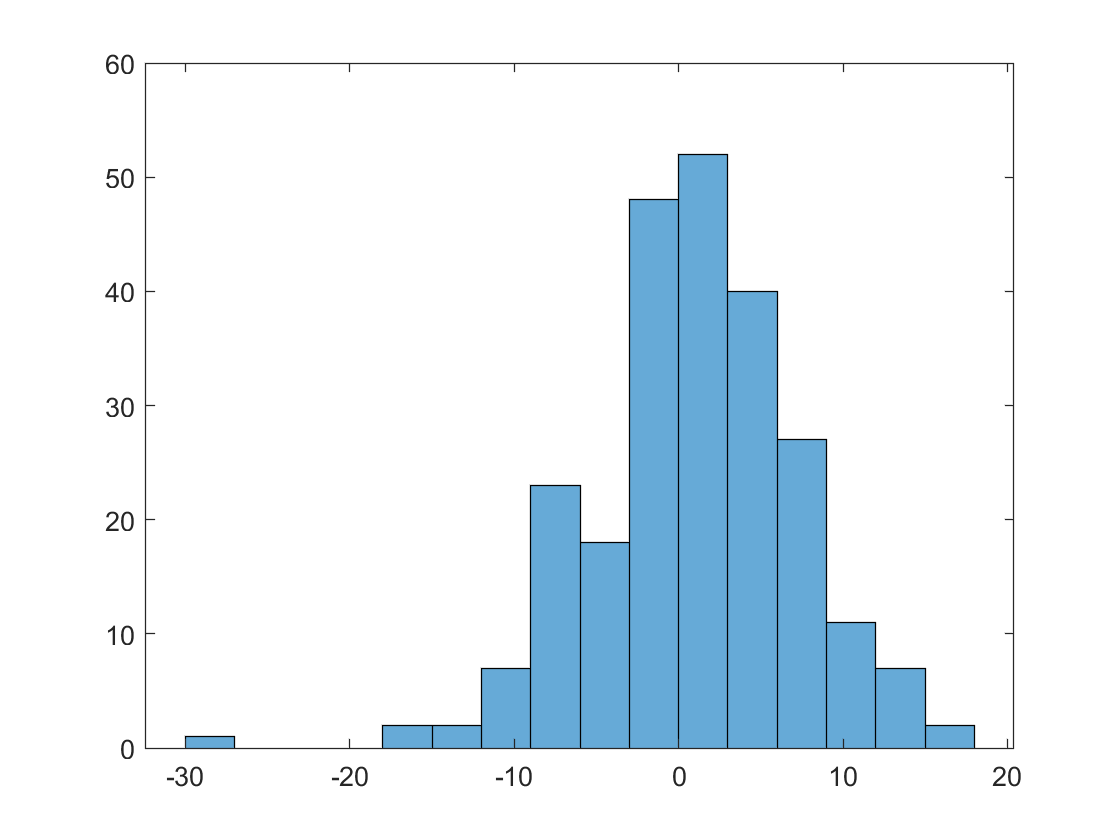

%   set a target amount, e.g., the maximum loss in a month in return
%   percentage form, say, -10%
monthly_shortfall=-10;

%   show the historigram of monthly returns
histogram(mret_vec)


%   caculate the shortfall probability (realized)
shortfall_prob_realized=sum(mret_vec<monthly_shortfall)/length(mret_vec)

shortfall_prob_realized = 0.0333


%   what is the theoretical shortfall probability assuming monthly returns
%   follow normal distribution with mean estimated by sample mean, and
%   variance estimated by sample variance.
z_value=(monthly_shortfall-mean_monthly)/sqrt(variance_monthly)

z_value = -1.7286


%   the theoretical short fall probability
shortfall_prob_theoretical=normcdf(z_value)

shortfall_prob_theoretical = 0.0419

          Shortfall probability has the advantage of being intuitive; however, it has some of the same problems as semivariance does. Forecasting is particularly difficult as the shortfall target becomes lower. At the extreme, proability forecasts for verly large shortfalls are influenced by perhaps only one or two observations.

- *Value at Risk*

        Given a probability point p, e.g., p=95%, VaR-p measures the maximum loss after excluding the worst (1-p) outcomes. Closely related to shortfall probability, this risk metric shares the same advantages and disadvantages. Another risk metric in this group is CVaR (Conditional Value at Risk, a.k.a., expected shortfall). These metrics all attempt to catpure the inherent risk on the left tail of the 'true' distribution of investment returns, because the normal distribution assumption may not strictly hold.

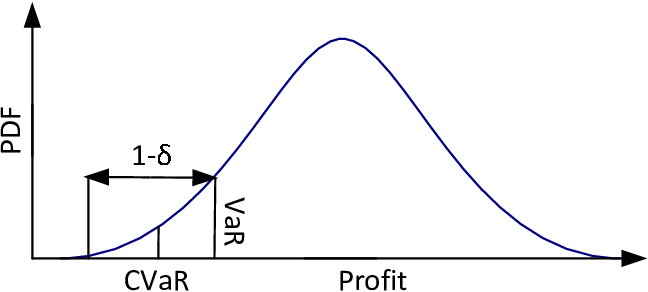

%   Value At Risk - 95%
%   i.e., choose the bottom 5% percentile threshold value
VaR=prctile(mret_vec,5)

%   CVaR: the mean return for all returns below the VaR threhold
CVaR=mean(mret_vec(mret_vec<VaR))

- *Maximum Drawdown*

         A drawdown for an asset (or a portfolio) measures the asset's price (or the portfolio's account size) drop from the previous high-water mark to the current level. Maxium drawdown is the maxium peak-to-trough drop in the observation time window. Maximum drawdown is an indicator of the maximum loss an investment could incur if choose the worst pair of on entry and exit time points. Related metric is [Calmar ratio](https://en.wikipedia.org/wiki/Calmar_ratio).

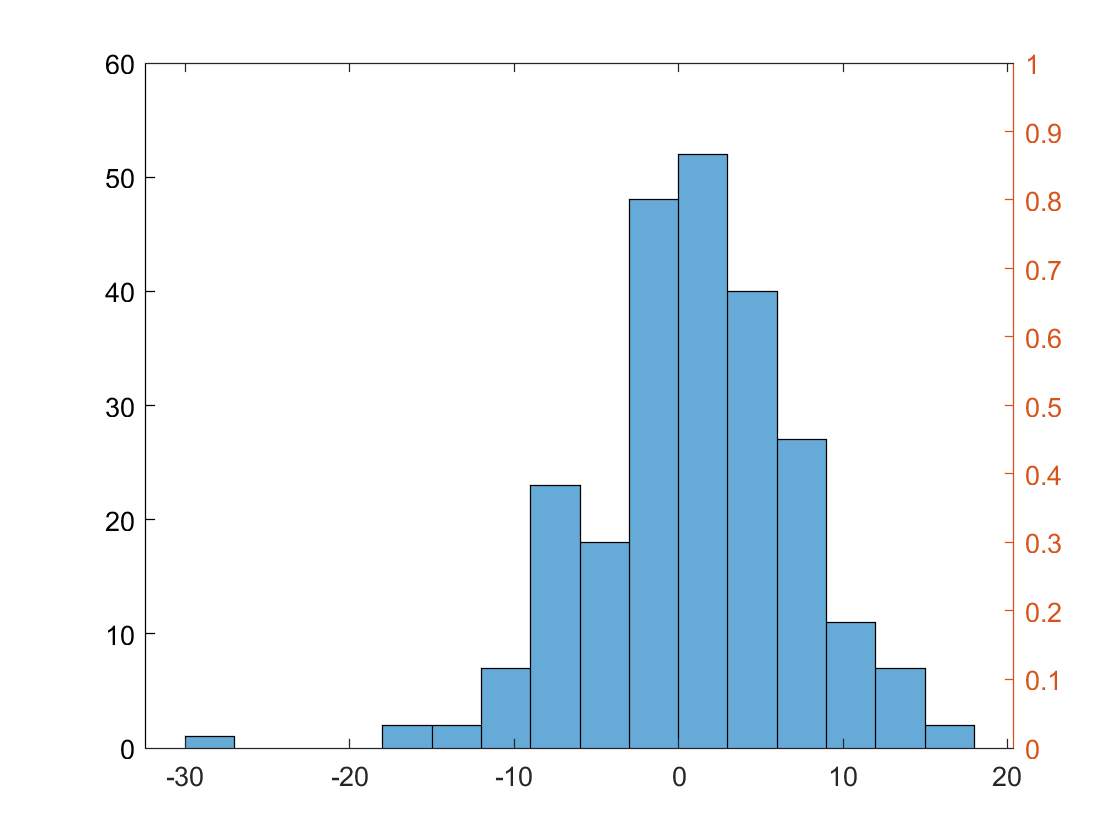

%   plot the portfolio value curve for the Emerging Market Equity
%   Benchmark
portval_vec=[1;cumprod(1+0.01*EM_mret)];
yyaxis left 
plot(portval_vec);

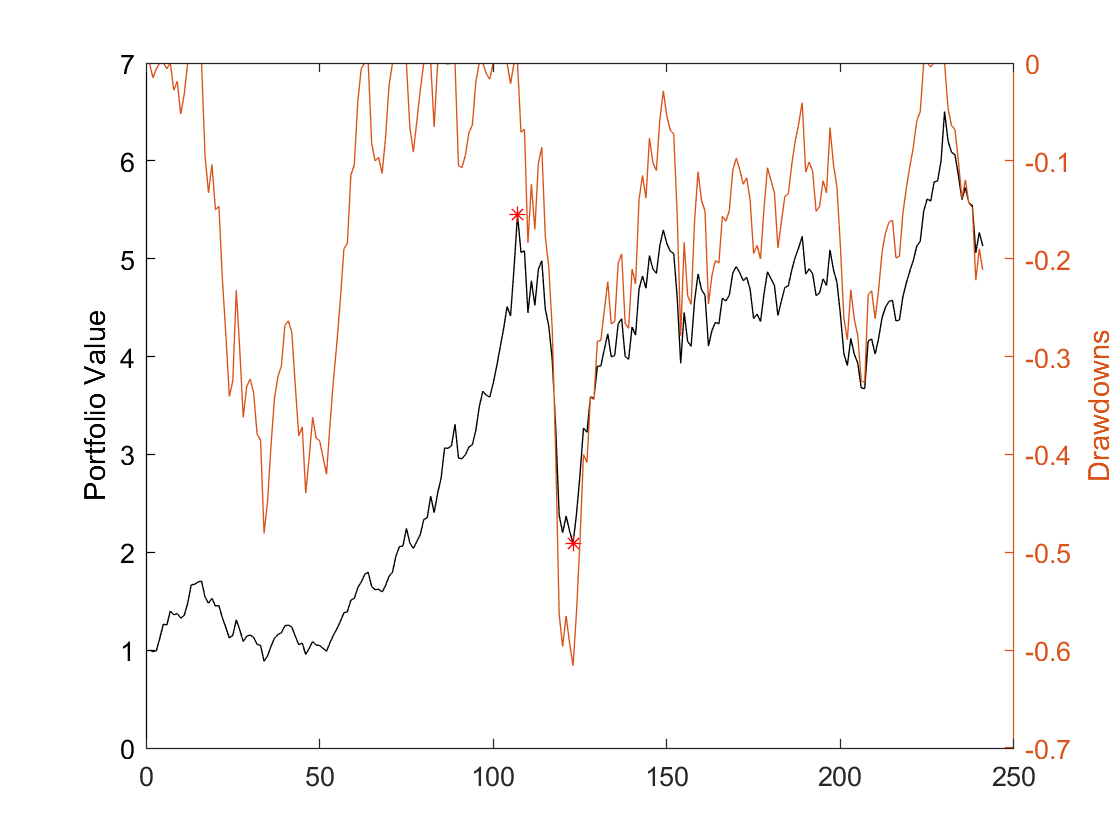

ylabel('Portfolio Value');

%   calculate drawdown at each time point
drawdown_vec=nan(length(portval_vec),1);
for i=1:length(portval_vec)
    drawdown_vec(i)=portval_vec(i)/max(portval_vec(1:i))-1;
end
yyaxis right
plot(drawdown_vec);
ylabel('Drawdowns');

%   locate the maximum drawdown
[max_drawdown,pos_right]=min(drawdown_vec);
[blah,pos_left]=max(portval_vec(1:pos_right));
hold on
yyaxis left
plot([pos_left,pos_right],portval_vec([pos_left,pos_right]),'r*');


%   output the maximum drawdown
fprintf('Max Drawdown = %.1f%%.\n',max_drawdown*100);

Max Drawdown = -61.6%.


  These metrics are all important to be monitored in risk reporting and management, although risk is defined as standard deviation under most contexts (e.g., portfolio selection in Modern Portfolio Theory).

## *Section C: Modern Portfolio Theory*

MPT dates back to the seminal work of [Markowitz ](https://en.wikipedia.org/wiki/Harry_Markowitz)(1952). In his paper, Markowitz defined precisely what portflio selection means: "*the investor does (or should) consider expected-return a desirable thing and variance of return an undesirable thing*". Indeed, Markowitz introduced the mean-variance optimization framework based on the idea that for a given level of portfolio risk/variance, investors should choose the portfolio with the highest expected return. 

Assumptions of MPT

- No taxes, no trading cost, no market impact from trading, and investors can borrow unlimited amount of money at risk free rate

- Returns of investable assets are multivariately normally distributed

- Investors evaluate an investment's risk based on its variance/volatility level

- Investors attempt to maximize investment returns given their unique risk tolerance level

- All investors have access to the same set of information and have consensus on assets return profiles

Notations (we consider a universe of $N$assets, **the risk-free asset excluded**)

- $\mathit{w}$: a $N\times1$vector of weights, where $\mathit{w_i}$ is weight allocated to the $i$-th asset.

- $\mathit{\mu}$: a $N\times1$vector of asset expected returns.

- $\Sigma$: a $N\times N$matrix of covariance, where the $(i,j)$ element is the covariance value between returns of the $i$-th and the$j$-th assets.

- $\mathit{e}$:  a $N\times 1 $unit vector, i.e., $\mathit{e_i}=1, \forall i.$

- $\sigma$: a scalar value of standard deviation

In the mean-variance optimization framework of MPT, for each investor, the goal is to minimize a portfolio's risk when given the investor's maximum risk allowance, which is determined by the investor's risk aversion level.

                                                                                      **maximize**  $\mathit{w^T}\mathit{\mu}$

                                                                                     ** subject to ** $\mathit{w^T}\Sigma\mathit{w}\leq\mathit{\sigma^2, \mathit{w^T}e=\text{1}$

The constraint of weight summing up to 1 means we only consider portfolios which are fully invested with net leverage of 1. Note that the above optimization problem may have no feasible solution for an arbitrarily specified risk level $\sigma$. The optimization problem can be solved by introducing Lagrange multipliers and analyzing the KKT conditions.** Efficient frontier** is the set of optimal portfolios from the mean-variance optimizations as we continuously change risk level $\sigma$ from the lowest-possible to the highest-possible volatility values. 

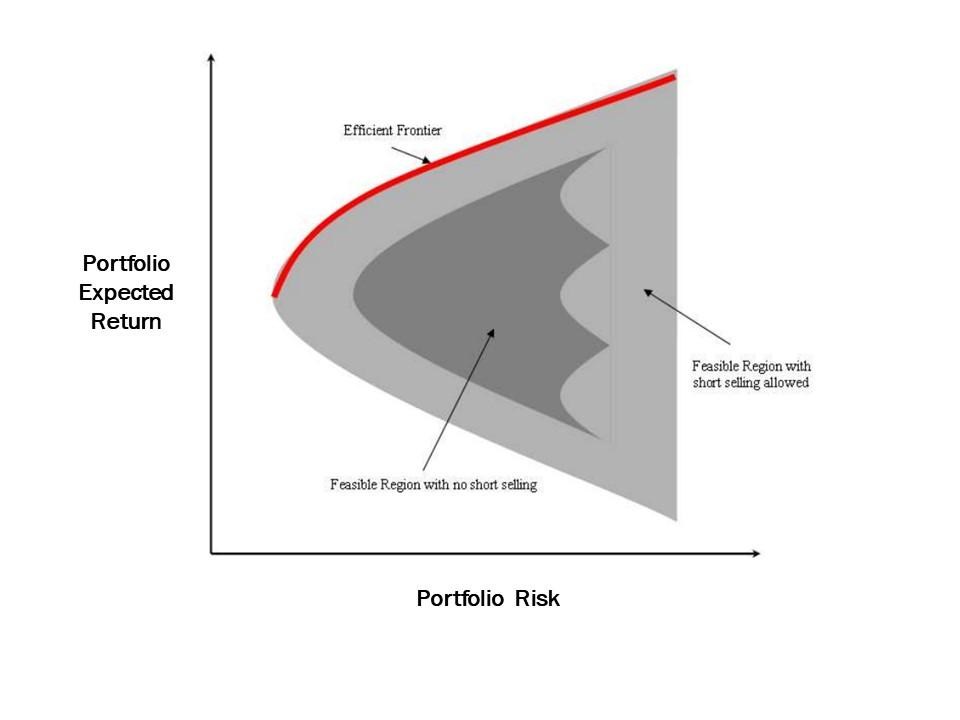 

*Do we need to run mean-variance optimization at each risk level in order to pinpoint its corresponding efficint portfolio? Short answer: ****No****.*

**The Two-Fund Theorem: **if we already know two different efficient portfolios with weight vectors $\mathit{w}1$ and $w2$, then the weight vector of any portfolio on the efficient frontier is a linear combination of $\mathit{w}1$ and $w2$. 

*Comments: the two ready-for-use efficient portfolios are ****the minimum variance portfolio**** with weight vector *$w_{minv}=\frac{\Sigma^{-1}e}{e^T\Sigma^{-1}e}$*, and ****the pseudo-maximum Sharpe Ratio*** ***portfolio**** (assuming 0 risk-free rate) with the weight vector *$w_{msr}=\frac{\Sigma^{-1}\mu}{e^T\Sigma^{-1}\mu}$*.*

%   the investable universe
ac_name'

ans = 12×1 cell array
    {'Fixed-Income: Treasury Inflation Protected Securities (TIPS)'     }
    {'Fixed-Income: U.S. Treasury Bonds and Investment Grade Corp Bonds'}
    {'Fixed-Income: U.S. High Yield Corp Bonds'                         }
    {'Fixed-Income: Non U.S. Sovereign Bonds'                           }
    {'Equities: U.S. Large Cap Growth'                                  }
    {'Equities: U.S. Large Cap Value'                                   }
    {'Equities: U.S. Small Cap Growth'                                  }
    {'Equities: U.S. Small Cap Value'                                   }
    {'Equities: Developed Countries Non-US '                            }
    {'Equities: Emerging Markets'                                       }
    {'Commodities'                                                      }
    {'Real Estate'                                                      }


%   calculate the covariance matrix based on their historical monthly
%   return data 
%   note: we annualize the covariance matrix by multiplying the matrix with 12
Sigma=nancov(ac_mret)*12;

%   let's use the historical annualized  as our estimates of asset
%   expected returns
ExpRet=nan(length(ac_name),1);
for ii=1:length(ac_name)
    ExpRet(ii)=geomean(1+0.01*ac_mret(:,ii))^12*100-100;
    fprintf('Annualized Return=%.2f%% for %s.\n',ExpRet(ii),ac_name{ii});
end

Annualized Return=5.20% for Fixed-Income: Treasury Inflation Protected Securities (TIPS).
Annualized Return=4.55% for Fixed-Income: U.S. Treasury Bonds and Investment Grade Corp Bonds.
Annualized Return=6.30% for Fixed-Income: U.S. High Yield Corp Bonds.
Annualized Return=3.40% for Fixed-Income: Non U.S. Sovereign Bonds.
Annualized Return=5.05% for Equities: U.S. Large Cap Growth.
Annualized Return=6.15% for Equities: U.S. Large Cap Value.
Annualized Return=6.14% for Equities: U.S. Small Cap Growth.
Annualized Return=8.23% for Equities: U.S. Small Cap Value.
Annualized Return=3.52% for Equities: Developed Countries Non-US .
Annualized Return=8.52% for Equities: Emerging Markets.
Annualized Return=0.57% for Commodities.
Annualized Return=9.65% for Real Estate.



%   unit vector
unit_vec=ones(length(ac_name),1);

%   calculate the minimum variance portfolio and the pseudo-maximum sharpe
%   ratio portfolio
Sigma_inv=inv(Sigma);
w_minv=Sigma_inv*unit_vec/(unit_vec'*Sigma_inv*unit_vec);
w_msr=Sigma_inv*ExpRet/(unit_vec'*Sigma_inv*ExpRet);
[w_minv,w_msr]

ans =    -0.2648   -0.1828
    1.2018    1.1267
    0.0495    0.0833
   -0.0480   -0.0695
    0.0311    0.0653
    0.0757    0.0430
   -0.0032   -0.0586
    0.0372    0.1238
   -0.0335   -0.1366
   -0.0242    0.0446


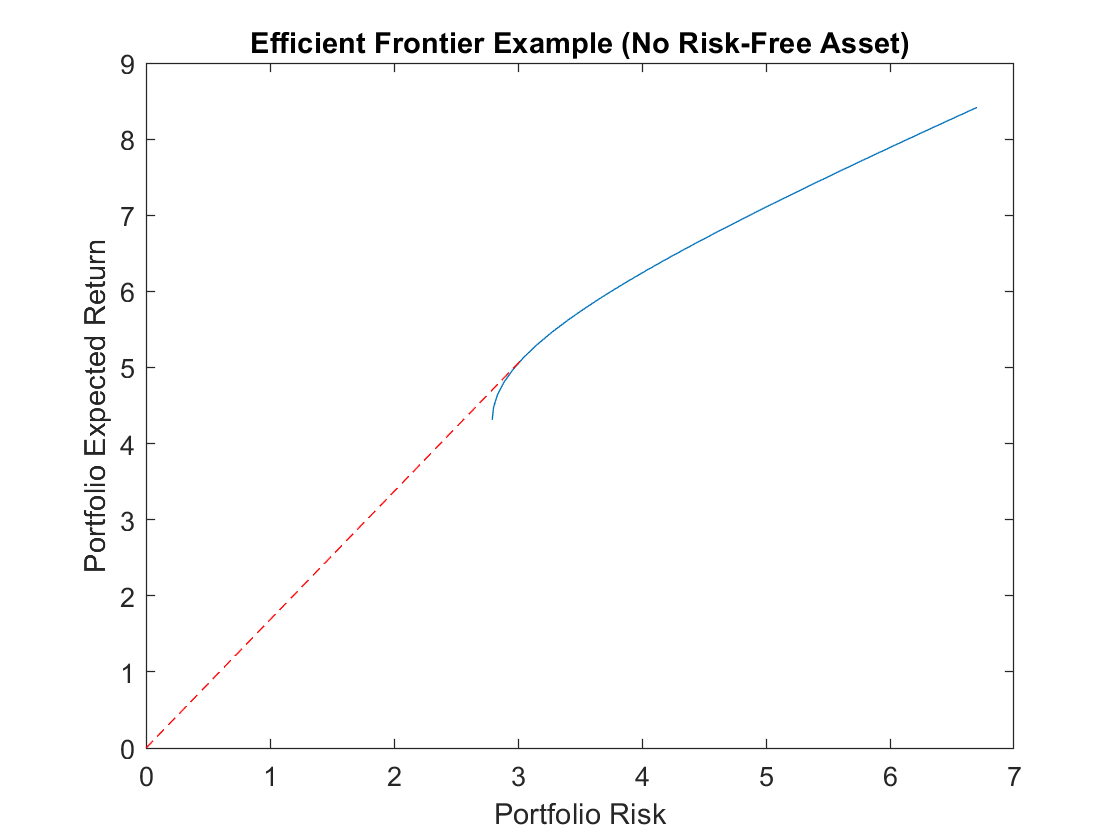


%   build the efficient frontier

%   define a function for weight vector in terms a combination of two known
%   portfolios
wt_func=@(c) (1-c)*w_minv+c*w_msr;

%   portfolio return and volatility function
pret_func=@(c) ExpRet'*wt_func(c);
prisk_func=@(c) sqrt(wt_func(c)'*Sigma*wt_func(c));

%   efficient frontier
c=0:0.2:5;
close();
plot(arrayfun(prisk_func,c),arrayfun(pret_func,c));
title('Efficient Frontier Example (No Risk-Free Asset)')
xlabel('Portfolio Risk')
ylabel('Portfolio Expected Return')
hold on
plot([0,prisk_func(1)],[0,pret_func(1)],'--','Color','r');

%   an exercise of solving mean-variance optimzation (MVO) problem
%   let's check w_msr is indeed an solution of MVO

%   we'll formulate the MVO in the other way, i.e., minimize risk while
%   put return target on constraint
target_ret=ExpRet'*w_msr;

%   objective function 
fun=@(w) w'*Sigma*w;

%   initial guess
w0=ones(length(ac_name));
w0=w0/sum(w0);

%   constraint 1: target return
%   Ax<=b
A=-ExpRet';
b=-target_ret;

%   constraint 2: fully invested
Aeq=ones(1,length(ac_name));
beq=1;

%   run the optimization
w_est=fmincon(fun,w0,A,b,Aeq,beq);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

[w_msr,w_est]

ans =    -0.1828   -0.1828
    1.1267    1.1267
    0.0833    0.0833
   -0.0695   -0.0695
    0.0653    0.0653
    0.0430    0.0430
   -0.0586   -0.0586
    0.1238    0.1238
   -0.1366   -0.1366
    0.0446    0.0446


## What if we add a risk-free asset to the investable universe? 

### Leading to the Capital Asset Pricing Model (CAPM).